# Simple Spectrogram

- sample bird call audio 

[channels, sample_rate] = audioread('../datasets/XC403881.wav');
whos;

  Name                  Size              Bytes  Class     Attributes

  channels         450879x2             7214064  double              
  sample_rate           1x1                   8  double              



- note there are 2 channels

- play the audio

soundsc(channels, sample_rate);
N = length(channels);
t = (0:N-1)/sample_rate;

- plot the channels

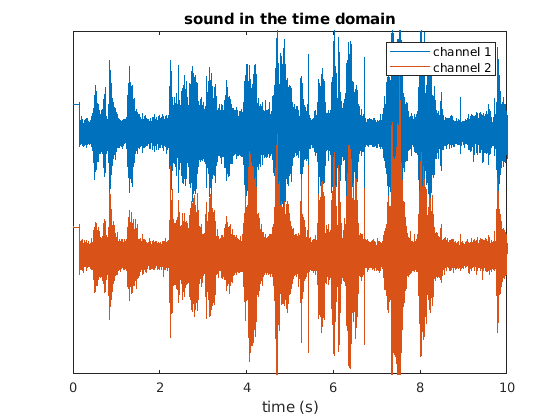

f1 = figure(1); clf;
f1.Position = [0 0 600 300];
plot(t, bsxfun(@plus, channels, [.25 0])); %offset the channels
xlabel("time (s)");
title("sound in the time domain");
xlim([0 10]);
ylim([-.3 .4]);
yticks([]);
legend(["channel 1", "channel 2"]);

- compute and plot the power spectrum

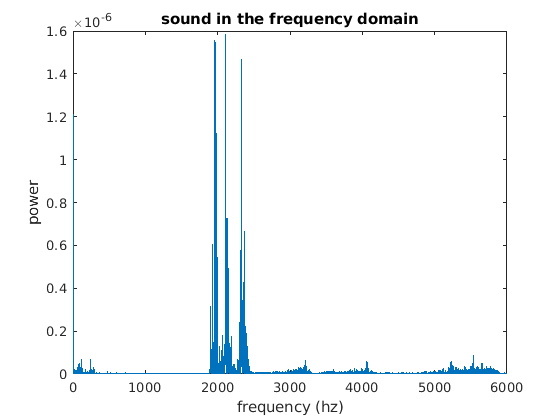

hz_vals = linspace(0, sample_rate/2, floor(N/2)+1);
powers = abs(fft(detrend(channels(:,1)))/N).^2;

f2 = figure(2); clf;
f2.Position = [0 0 500 300];
plot(hz_vals, powers(1:length(hz_vals)));
xlabel("frequency (hz)");
ylabel("power");
title("sound in the frequency domain");
xlim([0 6000]);

## Now Apply spectrogram

- use function in signal processing tool box

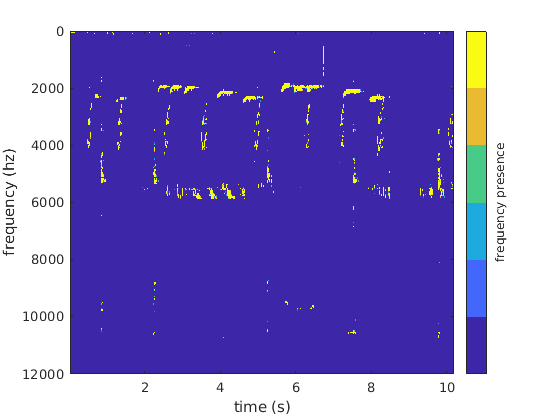

[spectrum, frequency, time] = spectrogram(detrend(channels(:,1)), hann(1000), 100, [], sample_rate);

f3 = figure(3); clf;
f3.Position = [0 0 600 300]; 
imagesc(time, frequency, abs(spectrum).^2);
ax = gca;
ax.CLim = [3 4];
ax.YLim = frequency([1 dsearchn(frequency, 12000)]);
ax.XLim = time([1 end]);
colormap(parula(6));
c = colorbar();
c.Label.String = "frequency presence";
set(c, 'YTick', []);
xlabel("time (s)");
ylabel("frequency (hz)");

### Separate the sources

- visually inspect the spectrogram to identify frequencies of interest